% MATLAB Script for Q4: LQR Tracking Controller Design
% LQR part is designed as before.
% The PID controller for comparison is defined by MANUALLY INPUT COEFFICIENTS,
% and its simulation uses logic adapted from Q3 script.

%--------------------------------------------------------------------------
% Exam Requirements for Q4:
% (a) Modify system for tracking h_ref(t).
% (b) Choose Q and R, explain each element.
% (c) Compare with a manually defined PID.
% Deliverables: Augmented system, simulations, comparison.
%--------------------------------------------------------------------------

clear; clc; close all;

%% --- 1. Load Plant Model and System Parameters from Q2 ---
fprintf('=== 1. Loading Plant Model from Q2 Results ===\n');

=== 1. Loading Plant Model from Q2 Results ===


q2_results_file = 'Q2_DynamicsAnalysis.mat';
if exist(q2_results_file, 'file')
    load(q2_results_file, 'selectedModel', 'selectedModelName', 'Ts');
    plant_sys = selectedModel; % This is the discrete-time plant model
    fprintf('Successfully loaded plant model "%s" and Ts = %.3f s from %s.\n', selectedModelName, Ts, q2_results_file);
else
    error('File %s not found. Please run Q2 script first to generate it.', q2_results_file);
end

Successfully loaded plant model "ARX Case A" and Ts = 0.050 s from Q2_DynamicsAnalysis.mat.



if ~isa(plant_sys, 'ss')
    try
        plant_sys = ss(plant_sys);
        fprintf('Converted loaded plant model to state-space.\n');
    catch ME
        error('Could not convert loaded plant model to state-space. Error: %s', ME.message);
    end
end

Converted loaded plant model to state-space.



A_plant = plant_sys.A;
B_plant = plant_sys.B;
C_plant = plant_sys.C;
D_plant = plant_sys.D;

n_plant = size(A_plant, 1);
m_plant = size(B_plant, 2);
p_plant = size(C_plant, 1);

if m_plant > 1 || p_plant > 1
    warning('LQR_TRACKING:MIMO', 'This LQR tracking script is primarily set up for SISO systems. Augmentation and Q/R choices might need adjustment for MIMO.');
end
if isempty(D_plant)
    D_plant = zeros(p_plant, m_plant);
end

fprintf('\n--- Original Plant State-Space Matrices (from Q2 model: %s) ---\n', selectedModelName);


--- Original Plant State-Space Matrices (from Q2 model: ARX Case A) ---


disp('A_plant ='); disp(A_plant);

A_plant =
    1.4507         0   -0.4579    0.0000
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0



disp('B_plant ='); disp(B_plant);

B_plant =
    0.0625
         0
         0
         0



disp('C_plant ='); disp(C_plant);

C_plant =
    0.0196    0.0287    0.0093         0



disp('D_plant ='); disp(D_plant);

D_plant =
     0



fprintf('Sampling Time Ts = %.3f s\n\n', Ts);

Sampling Time Ts = 0.050 s




%% --- 2. LQR Design: Augment System for Tracking ---
Aa = [A_plant,   zeros(n_plant, p_plant);
     -C_plant,   eye(p_plant)];
Ba = [B_plant;
     -D_plant];

fprintf('--- Augmented System Matrices for LQR Tracking Controller ---\n');

--- Augmented System Matrices for LQR Tracking Controller ---


disp('Aa ='); disp(Aa);

Aa =
    1.4507         0   -0.4579    0.0000         0
    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
   -0.0196   -0.0287   -0.0093         0    1.0000



disp('Ba ='); disp(Ba);

Ba =
    0.0625
         0
         0
         0
         0



na_lqr = size(Aa, 1);

%% --- 3. LQR Design: Choose Q and R Weighting Matrices ---
% --- USER ACTION: Define and Justify Q and R matrices ---
Qa_diag = ones(1, na_lqr);
if p_plant == 1
    Qa_diag(n_plant+1) = 1000; % Example: Penalize integrated error for SISO
else
    for i_p = 1:p_plant, Qa_diag(n_plant+i_p) = 100; end
end
% Qa = diag(Qa_diag);
Qa=diag([1 1 1 1 1000])

Qa =            1           0           0           0           0
           0           1           0           0           0
           0           0           1           0           0
           0           0           0           1           0
           0           0           0           0        1000



Ra_val = 0.5; % Example
Ra = Ra_val * eye(m_plant);

fprintf('\n--- LQR Weighting Matrices (USER TO TUNE AND JUSTIFY) ---\n');


--- LQR Weighting Matrices (USER TO TUNE AND JUSTIFY) ---


disp('Qa ='); disp(Qa); disp('Ra ='); disp(Ra);

Qa =
           1           0           0           0           0
           0           1           0           0           0
           0           0           1           0           0
           0           0           0           1           0
           0           0           0           0        1000

Ra =
    0.5000



fprintf('Reminder: Explain your choices for Qa and Ra elements in your report!\n');

Reminder: Explain your choices for Qa and Ra elements in your report!



%% --- 4. LQR Design: Compute LQR Gain ---
if ~all(eig(Ra) > 0), error('LQR_DESIGN:R_NOT_PD', 'R matrix must be positive definite.'); end
if rank(ctrb(Aa,Ba)) < na_lqr, warning('LQR_DESIGN:NOT_CTRL', 'Augmented system (Aa, Ba) is NOT controllable!'); end

[Ka_lqr, S_lqr, E_lqr_cl] = dlqr(Aa, Ba, Qa, Ra);

fprintf('\n--- LQR Gain Matrix (Ka_lqr) ---\n'); disp('Ka_lqr ='); disp(Ka_lqr);


--- LQR Gain Matrix (Ka_lqr) ---
Ka_lqr =
   14.3727   -1.5345   -4.1625    0.0000  -28.1417



fprintf('LQR closed-loop eigenvalues:\n'); disp(sort(E_lqr_cl));

LQR closed-loop eigenvalues:
   0.0000 + 0.0000i
  -0.4852 + 0.0000i
   0.6322 + 0.0000i
   0.7027 - 0.3120i
   0.7027 + 0.3120i



if any(abs(E_lqr_cl) >= 1), warning('LQR_DESIGN:UNSTABLE_POLES', 'LQR controller resulted in unstable closed-loop poles!'); end

%% --- 5. Simulation Setup Common for LQR and PID ---
sim_time_common = 15; % Common simulation time
t_vec_common = (0:Ts:sim_time_common)';
N_sim_common = length(t_vec_common);
h_ref_amplitude = 1.0;
h_ref_signal_common = h_ref_amplitude * ones(N_sim_common, p_plant);
x0_plant_sim = zeros(n_plant, 1); % Initial plant state for all simulations
xi0_error_sim = zeros(p_plant, 1); % Initial integrator state for LQR

%% --- 6. LQR Controller Simulation ---
fprintf('\n--- 6. Simulating LQR Tracking Controller ---\n');


--- 6. Simulating LQR Tracking Controller ---


x_lqr_plant_hist = zeros(n_plant, N_sim_common);
xi_lqr_error_hist = zeros(p_plant, N_sim_common);
y_lqr_hist = zeros(p_plant, N_sim_common);
u_lqr_hist = zeros(m_plant, N_sim_common);
% e_lqr_hist = zeros(p_plant, N_sim_common); % Error is implicitly handled by xi

current_x_plant_lqr = x0_plant_sim;
current_xi_error_lqr = xi0_error_sim;

for k = 1:N_sim_common
    x_lqr_plant_hist(:, k) = current_x_plant_lqr;
    xi_lqr_error_hist(:, k) = current_xi_error_lqr;
    current_xa_lqr = [current_x_plant_lqr; current_xi_error_lqr];
    current_u_lqr = -Ka_lqr * current_xa_lqr;
    current_y_lqr = C_plant * current_x_plant_lqr + D_plant * current_u_lqr;
    current_ref_val = h_ref_signal_common(k, :)';
    current_e_lqr = current_ref_val - current_y_lqr; % This error updates the integrator state
    u_lqr_hist(:, k) = current_u_lqr;
    y_lqr_hist(:, k) = current_y_lqr;
    % e_lqr_hist(:,k) = current_e_lqr; % Can log if needed
    if k < N_sim_common
        next_x_plant_lqr = A_plant * current_x_plant_lqr + B_plant * current_u_lqr;
        next_xi_error_lqr = current_xi_error_lqr + current_e_lqr; % Integral of current error e(k)
        current_x_plant_lqr = next_x_plant_lqr;
        current_xi_error_lqr = next_xi_error_lqr;
    end
end
lqr_stepinfo = stepinfo(y_lqr_hist(1,:)', t_vec_common, h_ref_amplitude, 'SettlingTimeThreshold', 0.02);
fprintf('LQR Performance: OS=%.2f%%, Ts=%.2fs, RiseT=%.2fs\n', lqr_stepinfo.Overshoot, lqr_stepinfo.SettlingTime, lqr_stepinfo.RiseTime);

LQR Performance: OS=5.83%, Ts=0.71s, RiseT=0.25s



%% --- 7. Define and Simulate Manual PID Controller (Adapted from Q3 Logic) ---
fprintf('\n--- 7. Define and Simulate Manual PID Controller ---\n');


--- 7. Define and Simulate Manual PID Controller ---



% --- USER ACTION: INPUT YOUR DESIRED PID COEFFICIENTS ---
Kp_manual_pid = 52.38;   % REPLACE with your Kp (Example from Balanced PID)
Ki_manual_pid = 31.63;   % REPLACE with your Ki
Kd_manual_pid = 21.68;   % REPLACE with your Kd
% Note: Your Q3 script did not explicitly define Tf for the pid objects using Kp,Ki,Kd directly.
% The pid() command will use a default Tf if not specified, or no filter if Kd=0.
% To be consistent with Q3's direct pid(Kp,Ki,Kd) usage, we can do the same.
% If you want to explicitly add/control a derivative filter, define Tf_manual_pid.
Tf_manual_pid = 0; % Set to 0 or a small value if no explicit filter, or calculate one
                   % Example: Tf_manual_pid = Kd_manual_pid / (10 * Kp_manual_pid) if Kp !=0; else some default like 0.01
                   % For consistency with Q3's C_bal = pid(Kp_bal, Ki_bal, Kd_bal, 'Ts', Ts)
                   % which implies default Tf, we can create it similarly or specify Tf=0 for no filter effect if Kd used.
                   % The 'pid' command uses a default filter constant N=100 if Tf is not given and Kd is non-zero.
                   % To have NO filter explicitly when Kd is non-zero, one might set Tf to a very large value (less filtering)
                   % or use `pid(Kp,Ki,Kd,0,'Ts',Ts)` which is not standard.
                   % The default behavior of `pid(Kp,Ki,Kd,'Ts',Ts)` is usually what's intended from Q3.

fprintf('Using Manually Defined PID Coefficients:\n');

Using Manually Defined PID Coefficients:


fprintf('  Kp = %.4f\n', Kp_manual_pid);

  Kp = 52.3800


fprintf('  Ki = %.4f\n', Ki_manual_pid);

  Ki = 31.6300


fprintf('  Kd = %.4f\n', Kd_manual_pid);

  Kd = 21.6800



% Create the PID controller object (consistent with Q3's direct definition)
C_manual_pid = pid(Kp_manual_pid, Ki_manual_pid, Kd_manual_pid, 'Ts', Ts);
C_manual_pid.Name = 'Manually Defined PID';
manual_pid_name_for_plot = C_manual_pid.Name;

% Form closed-loop system (negative feedback assumed)
sys_cl_manual_pid  = feedback(C_manual_pid * plant_sys, 1);

% Get step response data and info
fprintf('Analyzing step response for "%s"...\n', C_manual_pid.Name);

Analyzing step response for "Manually Defined PID"...


[y_pid_hist, t_pid_sim_step] = step(sys_cl_manual_pid, t_vec_common); % t_pid_sim_step should align with t_vec_common
pid_stepinfo = stepinfo(sys_cl_manual_pid, 'SettlingTimeThreshold', 0.02); % Uses 2% criterion

% For plotting u(t), we need a manual simulation loop for the PID as well
% (as the 'step' function only gives y(t) for the closed-loop system directly)
fprintf('Performing manual simulation for "%s" to get control input u(t)...\n', C_manual_pid.Name);

Performing manual simulation for "Manually Defined PID" to get control input u(t)...


sys_pid_ss = ss(C_manual_pid); % Convert PID to state-space for manual loop
A_pid_ss = sys_pid_ss.A; B_pid_ss = sys_pid_ss.B;
C_pid_ss = sys_pid_ss.C; D_pid_ss = sys_pid_ss.D;
n_pid_states = size(A_pid_ss, 1);

u_pid_hist = zeros(m_plant, N_sim_common);
% y_pid_hist_manual_loop = zeros(p_plant, N_sim_common); % y_pid_hist from step() is already accurate
% e_pid_hist_manual_loop = zeros(p_plant, N_sim_common);

current_x_plant_for_pid_man_loop = x0_plant_sim;
current_pid_controller_states_man_loop = zeros(n_pid_states, 1);

for k = 1:N_sim_common
    y_for_error_calc_man_loop = C_plant * current_x_plant_for_pid_man_loop;
    current_ref_val_man_loop = h_ref_signal_common(k, :)';
    current_e_pid_man_loop = current_ref_val_man_loop - y_for_error_calc_man_loop;
    current_u_pid_man_loop = C_pid_ss * current_pid_controller_states_man_loop + D_pid_ss * current_e_pid_man_loop;
    u_pid_hist(:, k) = current_u_pid_man_loop; % Store control input
    % y_pid_hist_manual_loop(:,k) = C_plant * current_x_plant_for_pid_man_loop + D_plant * current_u_pid_man_loop;
    % e_pid_hist_manual_loop(:,k) = current_e_pid_man_loop;
    if k < N_sim_common
        next_pid_controller_states_man_loop = A_pid_ss * current_pid_controller_states_man_loop + B_pid_ss * current_e_pid_man_loop;
        next_x_plant_for_pid_man_loop = A_plant * current_x_plant_for_pid_man_loop + B_plant * current_u_pid_man_loop;
        current_pid_controller_states_man_loop = next_pid_controller_states_man_loop;
        current_x_plant_for_pid_man_loop = next_x_plant_for_pid_man_loop;
    end
end
% Note: y_pid_hist from step(sys_cl_manual_pid, t_vec_common) is used for output plotting and stepinfo.
% The manual loop above is primarily to get u_pid_hist.

fprintf('Manually Defined PID ("%s") Stepinfo: OS=%.2f%%, Ts=%.2fs, RiseT=%.2fs\n', ...
    manual_pid_name_for_plot, pid_stepinfo.Overshoot, pid_stepinfo.SettlingTime, pid_stepinfo.RiseTime);

Manually Defined PID ("Manually Defined PID") Stepinfo: OS=3.47%, Ts=0.45s, RiseT=0.10s



%% --- 8. Comparative Plots and Analysis (Renumbered from 9) ---
fprintf('\n--- 8. Generating Comparative Plots and Preparing for Analysis ---\n');


--- 8. Generating Comparative Plots and Preparing for Analysis ---


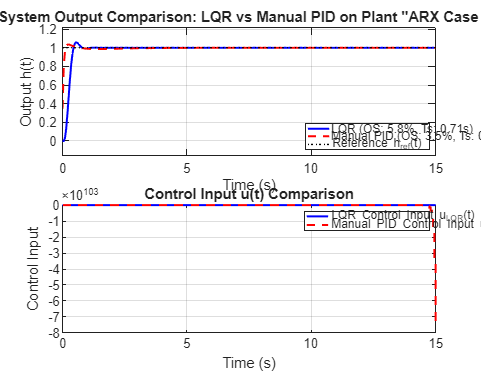

figure('Name', 'Q4: LQR vs Manually Defined PID Tracking Performance', 'Position', [50, 50, 900, 700]);

subplot(2,1,1); % Output Response y(t)
plot(t_vec_common, y_lqr_hist(1,:), 'b-', 'LineWidth', 1.5, 'DisplayName', sprintf('LQR (OS: %.1f%%, Ts: %.2fs)', lqr_stepinfo.Overshoot, lqr_stepinfo.SettlingTime));
hold on;
% Use y_pid_hist from step() for the closed-loop response plot
plot(t_vec_common, y_pid_hist(:,1), 'r--', 'LineWidth', 1.5, 'DisplayName', sprintf('Manual PID (OS: %.1f%%, Ts: %.2fs)', pid_stepinfo.Overshoot, pid_stepinfo.SettlingTime));
plot(t_vec_common, h_ref_signal_common(:,1), 'k:', 'LineWidth', 1, 'DisplayName', 'Reference h_{ref}(t)');
grid on; title(sprintf('System Output Comparison: LQR vs Manual PID on Plant "%s"', selectedModelName));
xlabel('Time (s)'); ylabel('Output h(t)'); legend('show', 'Location', 'SouthEast');
min_y_val = min([y_lqr_hist(1,:), y_pid_hist(:,1)', 0, h_ref_amplitude]); % y_pid_hist might be column
max_y_val = max([y_lqr_hist(1,:), y_pid_hist(:,1)', h_ref_amplitude]);
padding_y = 0.1 * (max_y_val - min_y_val) + 0.05*abs(h_ref_amplitude); ylim([min_y_val - padding_y, max_y_val + padding_y]);

subplot(2,1,2); % Control Input u(t)
stairs(t_vec_common, u_lqr_hist(1,:), 'b-', 'LineWidth', 1.5, 'DisplayName', 'LQR Control Input u_{LQR}(t)');
hold on;
stairs(t_vec_common, u_pid_hist(1,:), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Manual PID Control Input u_{PID}(t)');
grid on; title('Control Input u(t) Comparison'); xlabel('Time (s)'); ylabel('Control Input'); legend('show', 'Location', 'NorthEast');


fprintf('\n\n--- DELIVERABLES FOR Q4 REPORT ---\n');



--- DELIVERABLES FOR Q4 REPORT ---


fprintf('1. AUGMENTED SYSTEM MATRICES (Aa, Ba for LQR):\n'); disp('Aa ='); disp(Aa); disp('Ba ='); disp(Ba);

1. AUGMENTED SYSTEM MATRICES (Aa, Ba for LQR):
Aa =
    1.4507         0   -0.4579    0.0000         0
    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
   -0.0196   -0.0287   -0.0093         0    1.0000

Ba =
    0.0625
         0
         0
         0
         0



fprintf('\n2. LQR WEIGHTING MATRICES (Qa, Ra) AND JUSTIFICATION:\n'); disp('Qa ='); disp(Qa); disp('Ra ='); disp(Ra);


2. LQR WEIGHTING MATRICES (Qa, Ra) AND JUSTIFICATION:
Qa =
           1           0           0           0           0
           0           1           0           0           0
           0           0           1           0           0
           0           0           0           1           0
           0           0           0           0        1000

Ra =
    0.5000



fprintf('   >>> Provide your detailed justification for these Q and R choices in your report. <<<\n');

   >>> Provide your detailed justification for these Q and R choices in your report. <<<


fprintf('\n3. LQR GAIN MATRIX (Ka_lqr):\n'); disp('Ka_lqr ='); disp(Ka_lqr);


3. LQR GAIN MATRIX (Ka_lqr):
Ka_lqr =
   14.3727   -1.5345   -4.1625    0.0000  -28.1417



fprintf('\n4. MANUALLY DEFINED PID CONTROLLER COEFFICIENTS:\n');


4. MANUALLY DEFINED PID CONTROLLER COEFFICIENTS:


fprintf('   Kp = %.4f, Ki = %.4f, Kd = %.4f (Used default Tf for pid object)\n', Kp_manual_pid, Ki_manual_pid, Kd_manual_pid);

   Kp = 52.3800, Ki = 31.6300, Kd = 21.6800 (Used default Tf for pid object)


fprintf('\n5. SIMULATIONS (PLOTS):\n');


5. SIMULATIONS (PLOTS):


fprintf('   - The generated plot "Q4: LQR vs Manually Defined PID Tracking Performance" should be included.\n');

   - The generated plot "Q4: LQR vs Manually Defined PID Tracking Performance" should be included.


fprintf('\n6. COMPARISON OF LQR AND MANUALLY DEFINED PID:\n');


6. COMPARISON OF LQR AND MANUALLY DEFINED PID:


fprintf('   Performance Summary (from simulation/stepinfo):\n');

   Performance Summary (from simulation/stepinfo):


fprintf('   ---------------------------------------------------------------------\n');

   ---------------------------------------------------------------------


fprintf('   Metric             |   LQR Controller   |   Manually Defined PID\n');

   Metric             |   LQR Controller   |   Manually Defined PID


fprintf('   ---------------------------------------------------------------------\n');

   ---------------------------------------------------------------------


fprintf('   Overshoot (%%)      |      %6.2f      |      %6.2f \n', lqr_stepinfo.Overshoot, pid_stepinfo.Overshoot);

   Overshoot (%)      |        5.83      |        3.47 


fprintf('   Settling Time (s)  |      %6.3f      |      %6.3f \n', lqr_stepinfo.SettlingTime, pid_stepinfo.SettlingTime);

   Settling Time (s)  |       0.708      |       0.450 


final_lqr_y = mean(y_lqr_hist(1,max(1, N_sim_common-round(1/Ts)):N_sim_common)); 
final_pid_y_from_step = y_pid_hist(end,1); % From step() output, already settled if stable
fprintf('   Steady-State Err   |      %6.2e      |      %6.2e \n', abs(h_ref_amplitude-final_lqr_y), abs(h_ref_amplitude-final_pid_y_from_step));

   Steady-State Err   |      2.22e-16      |      7.06e-08 


fprintf('   ---------------------------------------------------------------------\n');

   ---------------------------------------------------------------------


fprintf('   (User should discuss how this manually defined PID compares to their findings in Q3, if relevant, and overall performance against LQR).\n');

   (User should discuss how this manually defined PID compares to their findings in Q3, if relevant, and overall performance against LQR).


fprintf('   >>> In your report, provide a qualitative and quantitative comparison focusing on tracking performance, transient response, control effort, etc. <<<\n');

   >>> In your report, provide a qualitative and quantitative comparison focusing on tracking performance, transient response, control effort, etc. <<<



%% --- 9. Optional: Save Q4 Results --- (Renumbered from 10)
q4_results_file = 'Q4_LQR_Design_ManualPID_v2.mat';
save(q4_results_file, 'plant_sys', 'Ts', 'selectedModelName', ...
     'Aa', 'Ba', 'Qa', 'Ra', 'Ka_lqr', 'lqr_stepinfo', ...
     'C_manual_pid', 'Kp_manual_pid', 'Ki_manual_pid', 'Kd_manual_pid', 'pid_stepinfo', ...
     't_vec_common', 'h_ref_signal_common', 'y_lqr_hist', 'u_lqr_hist', 'y_pid_hist', 'u_pid_hist');
fprintf('\nQ4 LQR design results and manual PID comparison data saved to %s.\n', q4_results_file);


Q4 LQR design results and manual PID comparison data saved to Q4_LQR_Design_ManualPID_v2.mat.


fprintf('\n=== Q4 LQR Tracking Controller Design Script Finished ===\n');


=== Q4 LQR Tracking Controller Design Script Finished ===
